# Echo

fs = 100

fs = 100

time = 1/fs:1/fs:1

time =     0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000


signal = sin(4*2*pi*time)

signal =     0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000


delayed = filter([0,0,0,0,0,0,1], 1, signal)

delayed =          0         0         0         0         0         0    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980   -0.9511   -0.8443   -0.6845   -0.4818   -0.2487   -0.0000    0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    0.9823    0.9048    0.7705    0.5878    0.3681    0.1253   -0.1253   -0.3681   -0.5878   -0.7705   -0.9048   -0.9823   -0.9980


echo = filter([1,0,0,0,0,0,1], 1, signal)

echo =     0.2487    0.4818    0.6845    0.8443    0.9511    0.9980    1.2310    1.3866    1.4551    1.4321    1.3192    1.1234    0.8570    0.5367    0.1827   -0.1827   -0.5367   -0.8570   -1.1234   -1.3192   -1.4321   -1.4551   -1.3866   -1.2310   -0.9980   -0.7024   -0.3626    0.0000    0.3626    0.7024    0.9980    1.2310    1.3866    1.4551    1.4321    1.3192    1.1234    0.8570    0.5367    0.1827   -0.1827   -0.5367   -0.8570   -1.1234   -1.3192   -1.4321   -1.4551   -1.3866   -1.2310   -0.9980


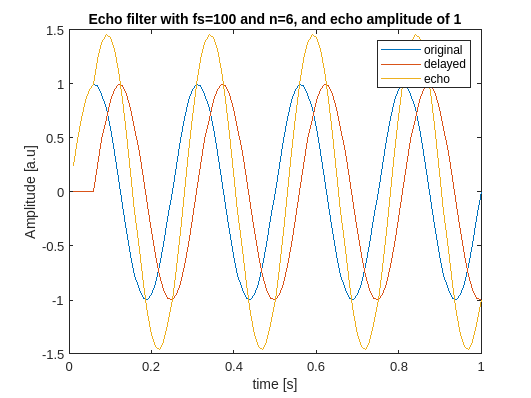


plot(time, signal)
hold on
plot(time, delayed)
plot(time, echo)
hold off
legend("original", "delayed", "echo")
title("Echo filter with fs=100 and n=6, and echo amplitude of 1")
xlabel("time [s]")
ylabel("Amplitude [a.u]")

# Equalizer

clear all;

[raw_signal, fs] = audioread("test_audio.wav")

raw_signal =    -0.0792
   -0.1153
   -0.0929
   -0.0229
    0.0279
   -0.0630
   -0.0312
   -0.0330
   -0.0022
    0.0218


fs = 44100

eq_signal = zeros(length(raw_signal), 1);

order = 2

order = 2

freq_shift = 1

freq_shift = 1


% Attempt to boost high hat
gain = [0.8, 0.8, 0.8, 0.8, 1, 2, 3, 3, 3, 2, 1, 1, 1]

gain =     0.8000    0.8000    0.8000    0.8000    1.0000    2.0000    3.0000    3.0000    3.0000    2.0000    1.0000    1.0000    1.0000



for n = 0:11
    lower_bound = log2(20)+(log2(22050)-log2(20))/12*n;
    upper_bound = log2(20)+(log2(22050)-log2(20))/12*(n+1);

    omega_low = 2^lower_bound/(fs/2)*freq_shift;
    omega_high = 2^upper_bound/(fs/2)/freq_shift;

    if n == 0 
        [b, a] = butter(order, omega_high, "low");
    elseif n == 11
        [b, a] = butter(order, omega_low, "high");
    else
        [b, a] = butter(order, [omega_low, omega_high], "bandpass");
    end

    % Apply gain
    b = b*gain(n+1);

    % equalize
    eq_signal = eq_signal + gain(n+1) * filter(b, a, raw_signal);

end

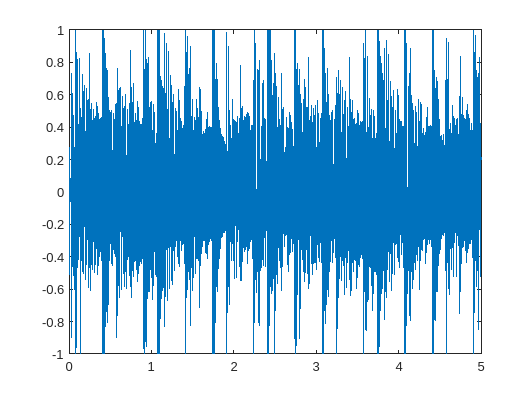

plot(1/fs:1/fs:length(raw_signal)/fs, raw_signal)

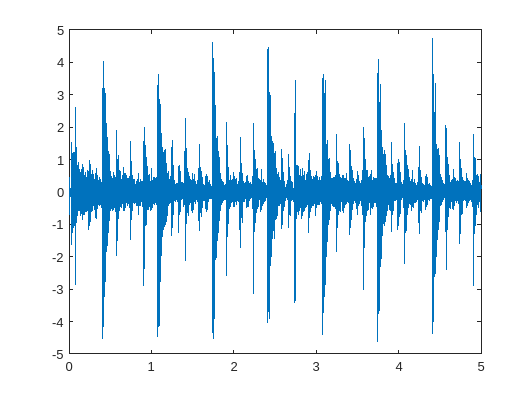

plot(1/fs:1/fs:length(raw_signal)/fs, eq_signal)

Play original

sound(raw_signal, fs)

Play eq'ed

sound(eq_signal, fs)